# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

file='cgam_model.xlsx';
data=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [REF] are valid
INFO: cStatusLogger. Exergy values [T1180] are valid
INFO: cStatusLogger. Exergy values [ETG87] are valid
INFO: cStatusLogger. Exergy values [ECMP84] are valid
INFO: cStatusLogger. Exergy values [RP84] are valid
INFO: cStatusLogger. Exergy values [PINCH10] are valid
INFO: cStatusLogger. Exergy values [CGAMR] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Resources Cost sample [TGASR] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model cgam_model.xlsx is valid


#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(4));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));

#### Compute Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables','ALL','ResourceSample',ResourceSample);

#### Show Results

printResults(res);

Process Exergy Cost

 Key   P*(MW)      Pe*(MW)     Pr*(MW)     F*(MW)      R*(MW)     
-------------------------------------------------------------------
 COMB       87.237      83.688       3.549      83.688       3.549
 COMP       56.569      54.268       2.301      56.569       0.000
 TURB      109.819     105.352       4.468     109.819       0.000
 HEAT       35.750      34.296       1.454      35.750       0.000
 HRSG       30.438      29.200       1.238      30.438      -0.000
 STCK        3.549       3.405       0.144       3.549       0.000


Process Unit Exergy Cost

 Key   kP*(J/J)    kPe*(J/J)   kPr*(J/J)   kF*(J/J)    kR*(J/J)    k(J/J)     
-------------------------------------------------------------------------------
 COMB       1.5120      1.4504      0.0615      1.0000      0.0615      1.4504
 COMP       1.9464      1.8672      0.0792      1.7750      0.0000      1.0966
 TURB       1.7750      1.7028      0.0722      1.7005      0.0000      1.0438
 HEAT       1.8989

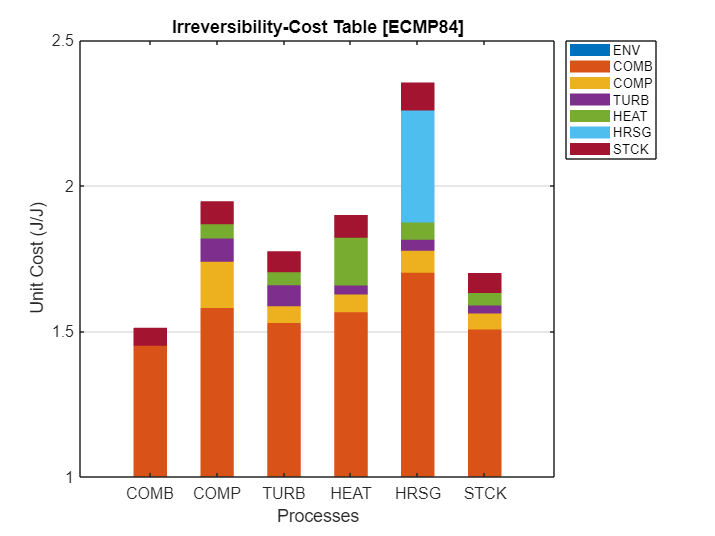

graphCost(res);